# **Test GJK 2D**

**Generate 100 no Collision Convex Shape**

clc;clear;close all
[filepath,~,~] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(filepath);
addpath(fullfile(filepath,'myfunc'),'-begin')

**Random Convex Parameter**

n_range = 20;
eps_range = 1.3;
r = 1;
r_ratio_range = 1.5;
ag_range = 75*pi/180;
trans_range = 20;

**Generate Convex**

num = 100;
Os = cell(num,1);
Os{1} = randShape2d(n_range,eps_range,r,r_ratio_range,ag_range,trans_range);
count = 1;

for i = 1:10000
    % Generate a Random Convex
    O = randShape2d(n_range,eps_range,r,r_ratio_range,ag_range,trans_range);

    % Check Collision with Others
    for j = 1:count
        dist =  gjk2d(O,Os{j});
        if dist==0
            break
        end
    end
    
    % No Collision, Add to the List
    if dist~=0
        count = count+1;
        Os{count} = O;
    end

    % Reach Number of Convex
    if count==num
        break
    end
end
i

i = 10000

### **Plot All Convex**

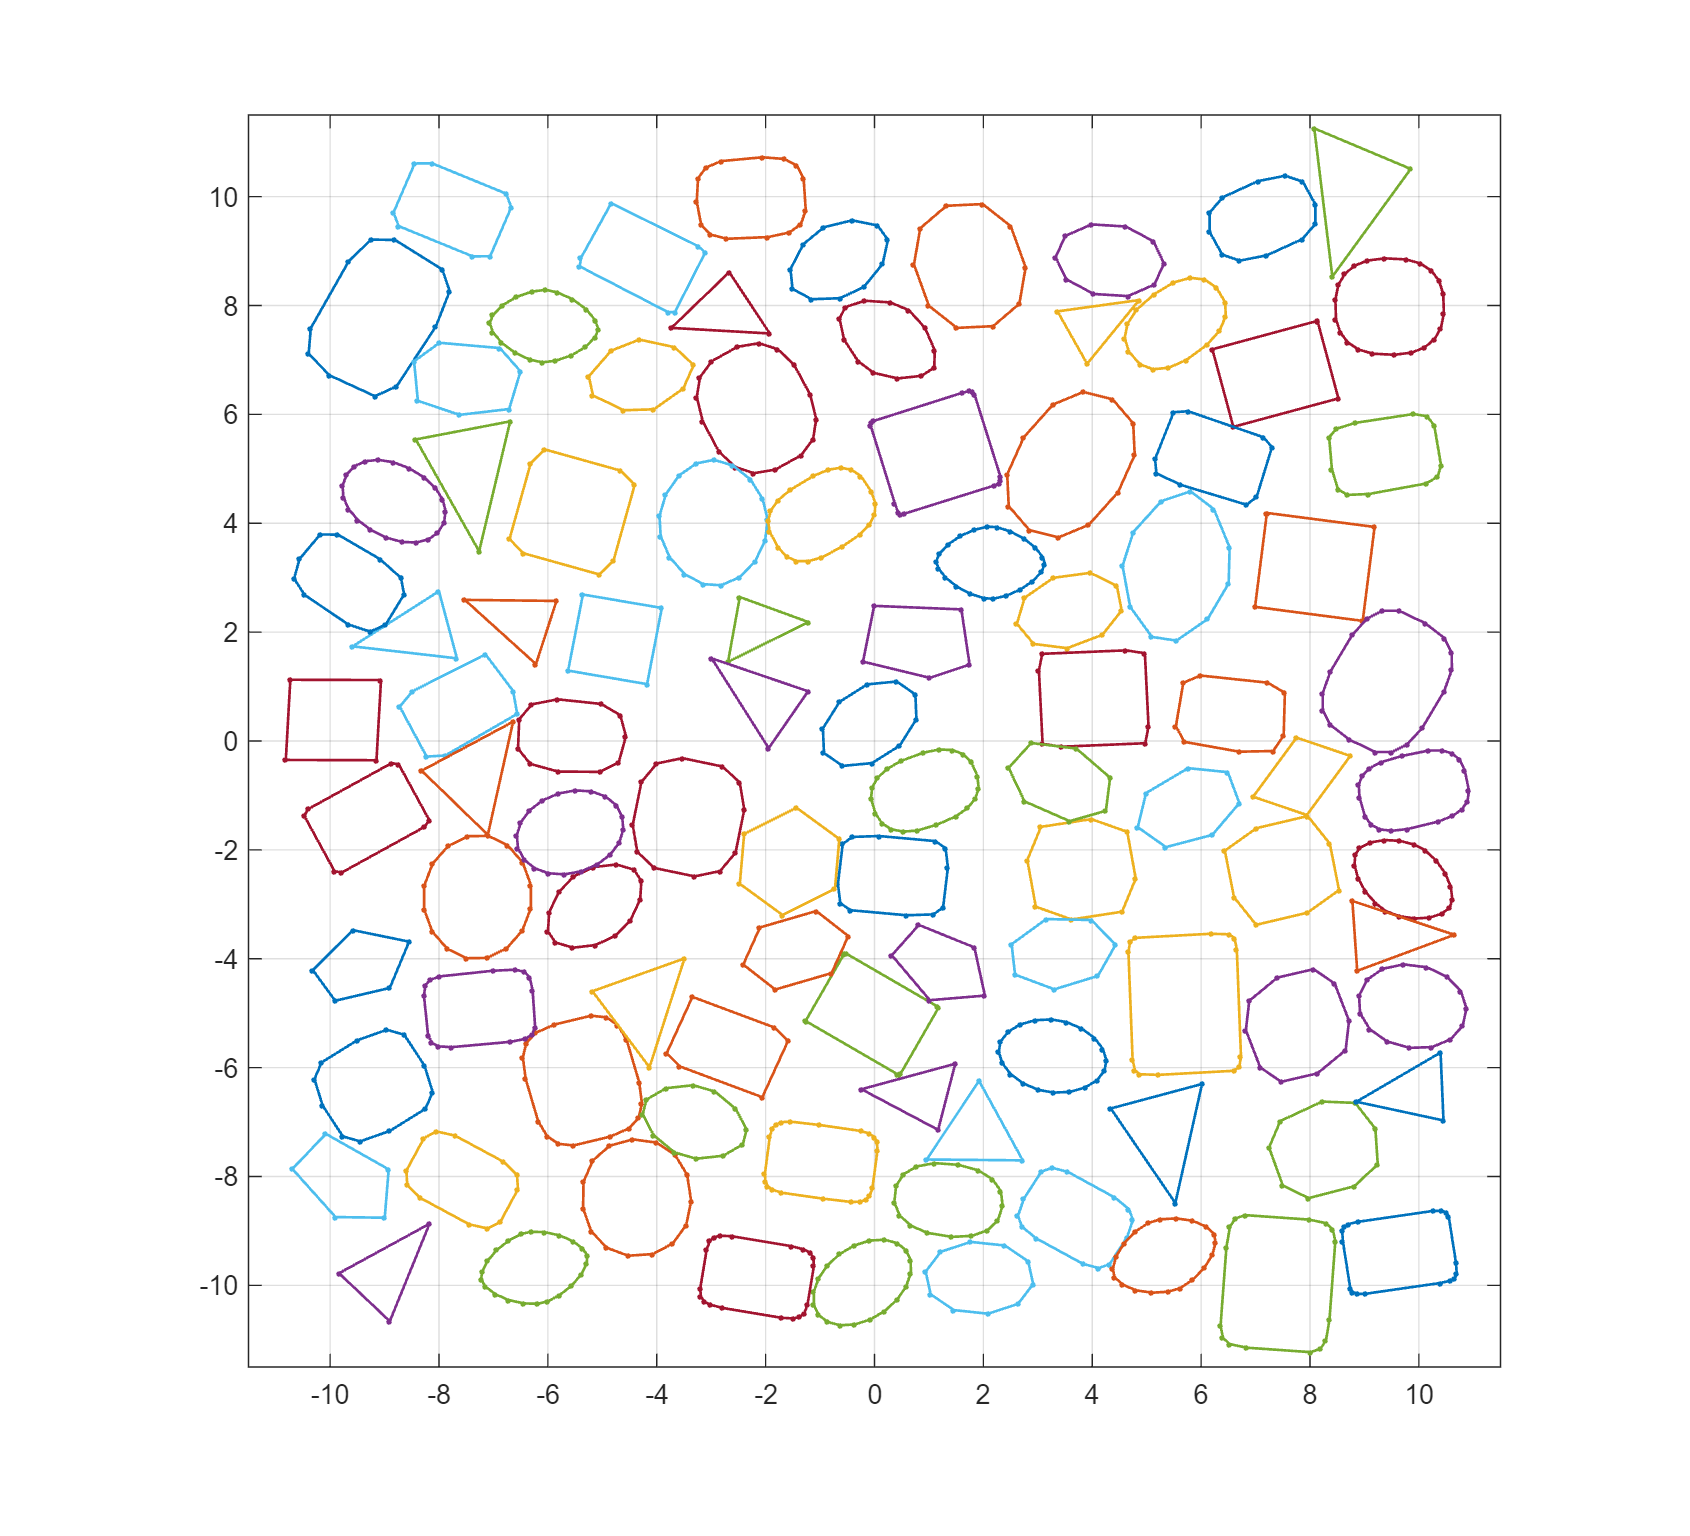

O_loop = ptsloop(Os(1:count));
f = figure;
for i = 1:length(O_loop)
    plot(O_loop{i}(1,:),O_loop{i}(2,:),'.-','LineWidth',1); hold on
end
grid on; axis equal
xlim([-11.5,11.5]); ylim([-11.5,11.5])
set(f,"Units","normalized","Position",[0,0,0.55,0.8])